# **Práctica 2: Análisis de la respuesta frecuencial de un sistema de control digital**

Las prácticas de la asignatura control por computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. Las sesiones P3 y P4 se dedican al diseño de controladores PID. Por último, en la práctica P5 se diseñarán controladores en campo frecuencial.

**OBJETIVO: Análisis de la respuesta frecuencial del sistema de control digital de velocidad. Análisis de la estabilidad mediante el criterio de Nyquist.**

**En esta sesión el estudiante ha de:**

- **Encontrar experimentalmente la respuesta frecuencial del sistema en lazo abierto.**

- **Aplicar el criterio de Nyquist para determinar el rango de valores de un controlador proporcional para que el sistema en lazo cerrado sea estable, y verificarlo experimentalmente.**

- **Comparar los resultados obtenidos con los resultados teóricos.**

% Alternar entre los datos del experimento y los del directorio Resultados
% Si desea usar los datos del directorio Resultados = false
% Si desea usar datos propios = true
useExperimentalData = false;

# Ejercicio 7: Obtención del diagrama de Nyquist

Usando los valores del modelo de la práctica 1 representar en un mismo diagrama la respuesta frecuencial de:

- El sistema en lazo abierto de velocidad de tiempo continuo.

- El sistema en lazo abierto de tiempo discreto con el periodo de muestreo de $T_s =0\ldotp 01s$.

- Identificar sobre las gráficas las zonas correspondientes a frecuencias altas y bajas.

- Justificar las diferencias que se observan entre las gráficas en cada una de las bandas de frecuencias.

% Parámetros de la planta
K_mot=0.82; %[rpm/V]
T_mot=0.24; %seg

% Periodo de muestreo
Ts=0.01;

% Función de transferencia continuo y digital del modelo
F=tf([K_mot],[T_mot 1])


F =
 
     0.82
  ----------
  0.24 s + 1
 
Continuous-time transfer function.



Fd=c2d(F,Ts)


Fd =
 
   0.03346
  ----------
  z - 0.9592
 
Sample time: 0.01 seconds
Discrete-time transfer function.



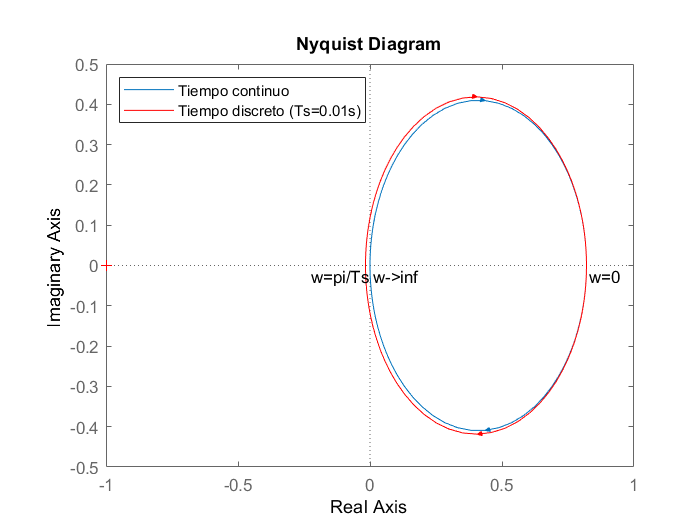


% Diagramas de Nyquist
figure
nyquist(F)
hold on 
nyquist(Fd,'red')
legend('Tiempo continuo',strcat('Tiempo discreto ',strcat(strcat(' (Ts=',num2str(Ts)),'s)')),'location','NorthWest');
text(dcgain(F)+0.010,-0.025,'w=0');
text(real(freqresp(Fd,pi/Ts))-0.205,imag(freqresp(Fd,pi/Ts))-0.025,'w=pi/Ts');
text(freqresp(F,inf)+0.010,freqresp(F,inf)-0.025,'w->inf');  

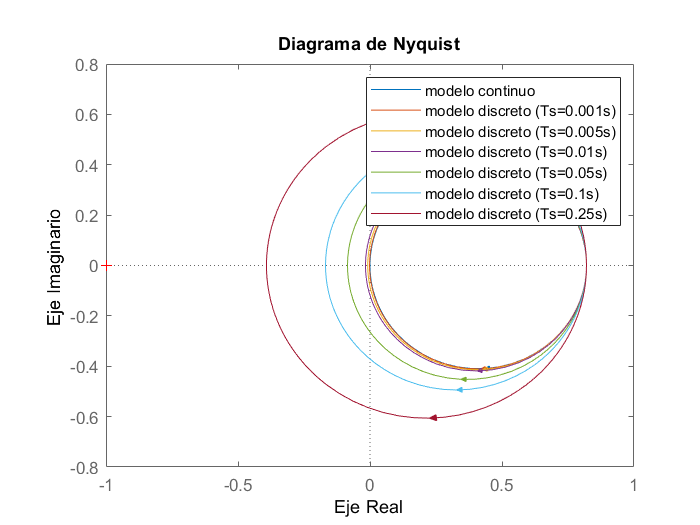


% Visualizamos el Nyquist para diferentes períodos de muestreo
    i=1;
    Ts=[0.001 0.005 0.01 0.05 0.1 0.25];
    [fils cols]=size(Ts);
    legenda={'modelo continuo'};
    while (i<=cols)
        legenda={char(legenda);strcat(strcat('modelo discreto (Ts=',num2str(Ts(1,i))),'s)')};
        i=i+1;
    end
    legenda=char(legenda);
    figure;
    nyquist(F);
    hold on;
    %legend('model continu');
    i=1;        
    while (i<=cols)
        nyquist(c2d(F,Ts(1,i),'zoh'));
        % legend(strcat(strcat('model discret(Ts=',num2str(Ts(1,i))),'s)'));
        i=i+1;
    end
    legend(legenda);
    title('Diagrama de Nyquist');
    xlabel('Eje Real');
    ylabel('Eje Imaginario');

Como se puede observar, a mayor Ts, más se acerca el diagrama al punto crítico (-1,0) con lo que el sistema se hace cada vez más inestable.

# Ejercicio 8: Obtención experimental del diagrama de Nyquist del sistema discreto

Abrir y ejecutar el modelo P2_Ex8.slx. Generar una señal senoidal de entrada de amplitud 2V y frecuencia 0,25Hz. Medir la ganancia y desfase de la señal de salida. Repetir el proceso para las frecuencias de 0.5, 0.8, 1, 2, 4, 5, 10, 20 y 50Hz. Usar un periodo de muestreo de 0,01 segundos.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



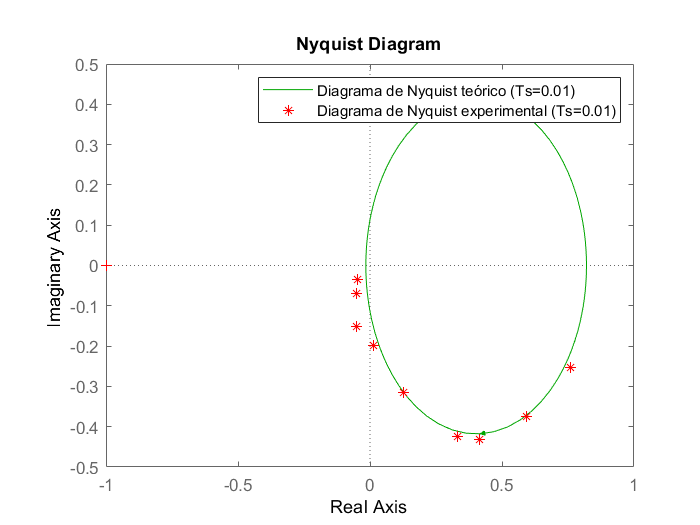

if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex8.slx
    run P2_Ex8.slx;
else
    % Vector de ganancias experimentales
    G=[0.8 0.7 0.6 0.54 0.34 0.2 0.16 0.085 0.06];
    % Vector de desfases experimentales (en radianes)
    F=[18.45 32.4 46.08 52 68.4 86.4 108 126 144]*(-pi/180);
    % Cálculo del complejo en forma cartesiana
    X=real (G.*exp(F*j));
    Y=imag(G.*exp(F*j));
    
    % Introducción de los parámetros de la planta
    K0=0.82;
    tau0=0.26;
    planta=tf([K0],[tau0,1])
    
    % Modelos de tiempo discreto
    Ts=0.01;
    plantad=c2d(planta,Ts,'zoh');
    
    % Dibujamos el diagrama de Nyquist teórico y experimental
    figure
    nyquist(plantad,'g')
    hold on
    plot(X,Y, 'r*' )
    legend('Diagrama de Nyquist teórico (Ts=0.01)','Diagrama de Nyquist experimental (Ts=0.01)')
end

Como podemos ver, el diagrama de Nyquist experimental se asemeja a la teórica. Las pequeñas diferencias vienen de los errores de cálculos, ya que a mayor frecuencia menor es la cantidad de muestras y más difícil se hace de medir los cambios producidos.

# Ejercicio 9: Aplicación del criterio de Nyquist

Usando el diagrama teórico aplicar el criterio de Nyquist para:

- Analizar la estabilidad del sistema de tiempo discreto.

- Encontrar el rango de valores del controlador proporcional $K_P$ que hacen que el sistema de tiempo discreto en lazo cerrado con realimentación de velocidad sea estable.

Compararlo con el caso de tiempo continuo comprobando cómo varían los diagramas teóricos al aumentar $K_P$. Verificar el resultado analizando la respuesta a escalón para $K_P$=5 y para un valor de $K_P$ fuera del rango, tanto en simulación como experimentalmente.


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



Ts = 0.0100


sistema_discreto =
 
   0.03094
  ----------
  z - 0.9623
 
Sample time: 0.01 seconds
Discrete-time transfer function.



gain = -0.0158

Kp_limit = 63.4225

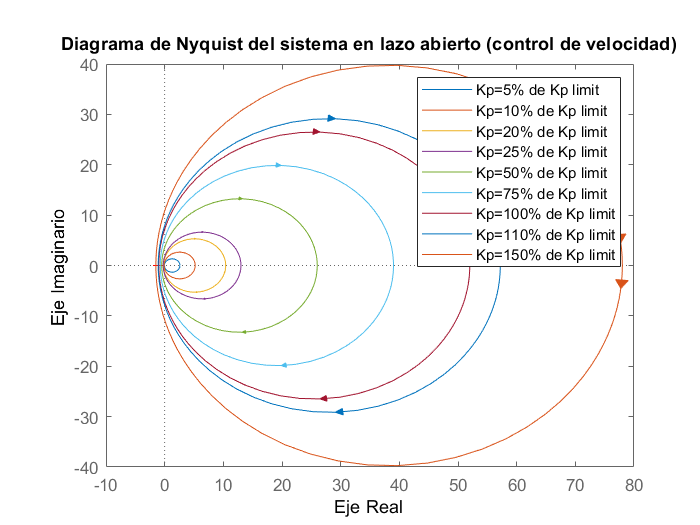

if useExperimentalData
    % Usar Simulink
    addpath([pwd filesep 'E2']);
    open P2_Ex9b.slx;
    run P2_Ex9b.slx;
else
    % Modelo del sistema (desde el fichero de la práctica 1: ejercicio 4)
    K0=0.82;
    tau0=0.26;
    planta=tf(K0,[tau0 1])
        
    % Periodo de muestreo
    Ts=0.01
    Kp=sym('K');
    
    % Determinación del sistema digital
    sistema_discreto=c2d(planta,Ts,'zoh')
    
    % Determinación de la Kp_limit
    gain=real(freqresp(sistema_discreto,pi/Ts))
    Kp_limit=-1/gain
    
    
    % Porcentajes de Kp_limit
    vector=[5 10 20 25 50 75 100 110 150];
    vector=[vector; vector*Kp_limit/100];
    [fils cols]=size(vector);
    i=1;
    figure;
    hold on;
    
    while (i<=cols)
        if (vector(1,i)<100)
            nyquist(sistema_discreto*vector(2,i));
        elseif (vector(1,i)==100)
            nyquist(sistema_discreto*vector(2,i));
        else
            nyquist(sistema_discreto*vector(2,i));
        end
        if (i==1)
            legenda={strcat(strcat('Kp=',num2str(vector(1,i))),'% de Kp limit')};
        else
            legenda={char(legenda);strcat(strcat('Kp=',num2str(vector(1,i))),'% de Kp limit')};        
        end
        i=i+1;
    end
    legenda=char(legenda);
    legend(legenda);
    title('Diagrama de Nyquist del sistema en lazo abierto (control de velocidad)');
    xlabel('Eje Real');
    ylabel('Eje Imaginario');
end

Como se puede observar, a mayor Kp, más grande es el diagrama de Nyquist, con lo cual, más inestable se vuelve el sistema. 

# Ejercicio 10: Obtención del diagrama de Bode teórico

Usando el modelo del sistema y la transformación bilineal $\mathrm{d2c}\left(\ldotp \ldotp \ldotp ,\mathrm{'Tustin'}\right)$, representar graficamente el diagrama de Bode y determinar a partir de este diagrama el margen de ganancia y el margen de fase. Relacionar el margen de ganancia con el $K_P$ crítico del apartado anterior.

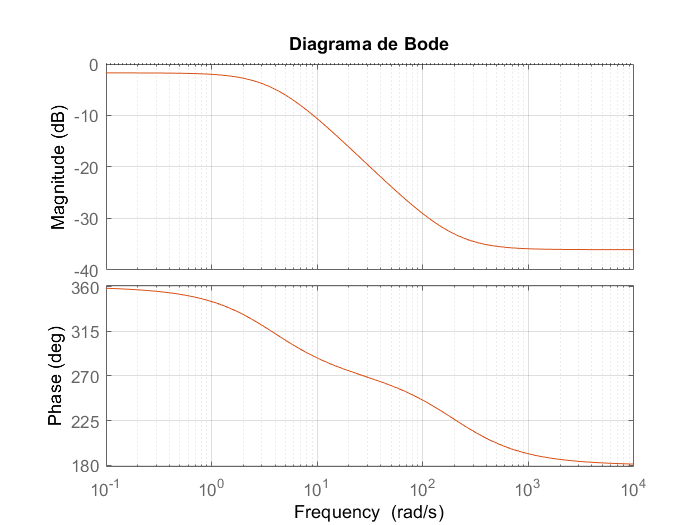

clc;
close all;
clear all;
% Modelo del sistema (abrimos el archivo creado en la práctica 1: ejercicio 4)
    K0=0.82;
    tau0=0.26;
    Kt=0.017;
    planta=tf([K0],[tau0 1]);
    
% Periodo de muestreo
Ts=0.01;

% Sistema teórico
sistema_discreto=c2d(planta,Ts,'zoh');
sistema_bilineal=d2c(sistema_discreto,'tustin');

% Imagen de Bode margenes de fase / ganancia
figure(1);
bode(sistema_bilineal);
hold on;
grid on;
[Gm,Pm,Wcg,Wcp]=margin(sistema_bilineal);
margin(sistema_bilineal);
title('Diagrama de Bode');

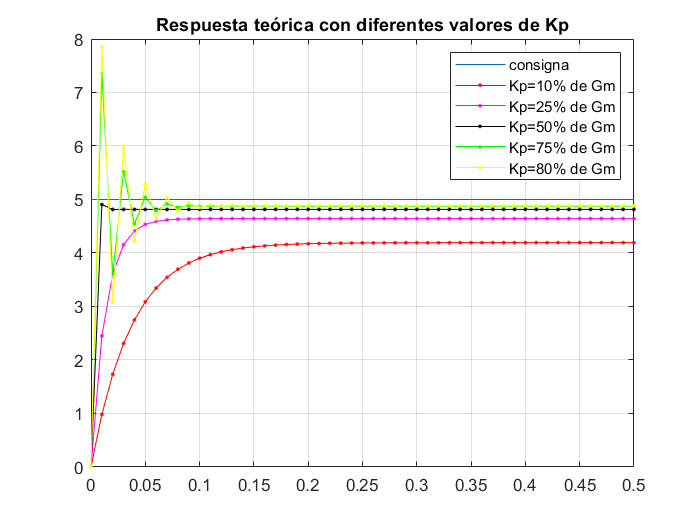


Vmax=5;
% Definición de un intervalo de tiempo
Tx=0.0:Ts:50*Ts;
% Definir referencia (escalón de Vmax de altura)
X =[Vmax*ones(size(Tx))];
% Definición de un conjunto de Kp con los que queremos simular el sistema, 
% expresado como un porcentaje de Gm (o Kp_max)
Kp=[10 25 50 75 80]';
Kp=[Kp (1/100)*Kp*Gm];
% Simular el comportamiento del sistema para diferentes Kp
[fils cols]=size(Kp);
i=1;
% El vector Y almacena las respuestas del sistema al escaloón con diferentes 
% constantes de proporcionalidad.

Y=[];
while (i<=fils)
    % La función model_discret (...) contiene una modelización del sistema 
    % en lazo cerrado y controlador proporcional
    Y=[Y; Kt*model_discret(0,K0/Kt,Kp(i,2),Kt,tau0,Ts,X)];
    i=i+1;
end

figure(2);
T_MAX=max(Tx);
T_MIN=min(Tx);
Y_MAX=max(max(Y));
Y_MIN=min(min(Y));

% Dibujar la referencia
plot(Tx,X);
hold on;
grid on;
% Dibujar simulaciones del sistema
i=1;
styles=['r.-';'m.-';'k.-';'g.-';'y.-';'c.-'];
[sty_fil sty_col]=size(styles);
legenda={'consigna'};
while (i<=fils)
    plot(Tx,Y(i,:),styles(mod(i,sty_fil),:));
    legenda={char(legenda);strcat(strcat('Kp=',num2str(Kp(i,1))),'% de Gm')};
    i=i+1;
end
title('Respuesta teórica con diferentes valores de Kp');
legenda=char(legenda);
legend(legenda);

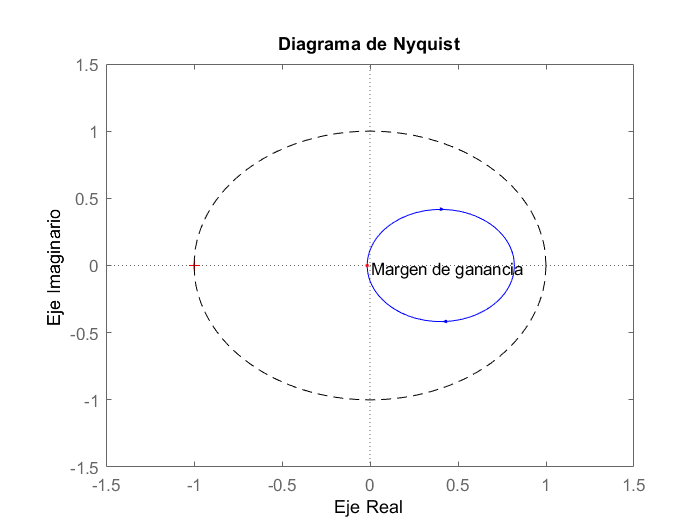


% Nyquist del sistema discreto
figure;
hold on;
nyquist(sistema_discreto,'b-');
freq_resp=freqresp(sistema_discreto,Wcp);
point=[real(freq_resp) imag(freq_resp)];

% Dibuje el punto correspondiente al margen de fase y margen de ganancia
text(point(1,1)+0.02,point(1,2)-0.02,'Margen de fase');
plot(point(1,1),point(1,2),'r.');
freq_resp=freqresp(sistema_discreto,pi/Ts);
point=[real(freq_resp) imag(freq_resp)];
text(point(1,1)+0.02,point(1,2)-0.02,'Margen de ganancia');
plot(point(1,1),point(1,2),'r.');
axis([-1.5 1.5 -1.5 1.5]);
title('Diagrama de Nyquist');
xlabel('Eje Real');
ylabel('Eje Imaginario');
x=[0 point(1,1)]';
y=[0 point(1,2)]';
circumf;